% Load a string (run notebook 3 to generate)
load("data/stringmain_n_10_fe/output.mat");

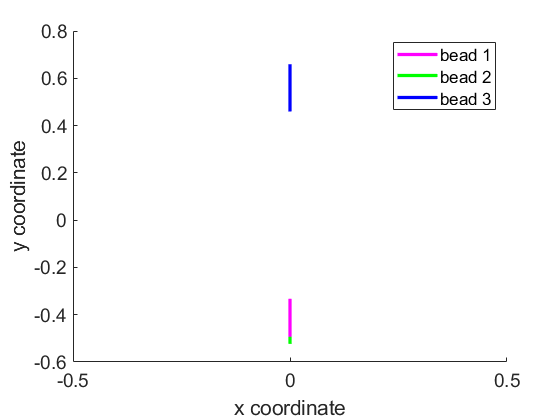

% Plot of the trajectory in 2d space
plot2dbeads(out.x);
axis([-0.5 0.5 -0.6 0.8])
legend("bead 1","bead 2", "bead 3");
set(gca, "FontSize", 14)
xlabel('x coordinate');
ylabel('y coordinate');
saveas(gcf,'figures/4a.png')

% Plot of coordinates
xx = linspace(0,1,10)

xx =          0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000


cm = hsv(3);
cm(1, :) = [1 0 1];
cmap = colormap(cm);

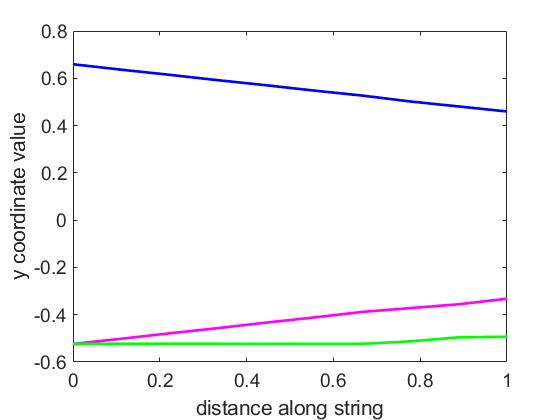

plot(xx,out.x(2,:)', "LineWidth", 2, 'Color', cmap(1, :));
hold on;
plot(xx,out.x(4,:)', "LineWidth", 2, 'Color', cmap(2, :));
plot(xx,out.x(6,:)', "LineWidth", 2, 'Color', cmap(3, :));
xlabel('distance along string');
ylabel('y coordinate value');
%legend("y_1","y_2","y_3", "Location", "bestoutside")
set(gca,"FontSize", 14)
saveas(gcf,'figures/4b.png')